% Load EmoDB (German) dataset provided by MathWorks
dataFolder = pwd;
dataset = fullfile(dataFolder, "EmoDB");
url = "http://emodb.bilderbar.info/download/download.zip";
disp("Downloading EmoDB (40.5 MB) ...")

unzip(url,dataset)
downloadFolder = matlab.internal.examples.downloadSupportFile("audio","SpeechEmotionRecognition.zip");
dataFolder = pwd;
unzip(downloadFolder,dataFolder)

% Read EmoDB dataset
ads = audioDatastore(fullfile("EmoDB/wav/"));
% Define indices in filename where emotion and speaker codes are stored (end-?)
emotionIdx = 5;
speakerIdx = [10, 9];
% Define mapping for emotions IDs in file name
emotionMapping = {["W","L","E","A","F","T","N"], ...
                  ["Anger","Boredom","Disgust","Anxiety/Fear","Happy","Sad","Neutral"]};
% Build label table for all files
labelTable = buildLabelTable(ads, emotionIdx, speakerIdx, emotionMapping);
ads.Labels = labelTable;
% Subset files to only include anger, happy, and neutral
ads = subset(ads, find(ismember(cellstr(ads.Labels.Emotion), ["Sad", "Happy", "Anger"])));
% Subsample emotions so classes are balanced for training
ads = subsampleFiles(ads);
% Finalize labels and summarize
summary(ads.Labels)

Variables:
    Speaker: 186×1 categorical
        Values:
            03       26   
            08       23   
            09       11   
            10       14   
            11       21   
            12       10   
            13       15   
            14       28   
            15       14   
            16       24   
    Emotion: 186×1 categorical
        Values:
            Anger              62   
            Anxiety/Fear        0   
            Boredom             0   
            Disgust             0   
            Happy              62   
            Neutral             0   
            Sad                62   


% Load the sampling frequency from file
netFolder = fullfile(pwd,"SpeechEmotionRecognition");
load(fullfile(netFolder,"network_Audio_SER.mat"));
fs = afe.SampleRate;

% Split dataset into train/test sets
[ads_train, ads_test] = splitTrainTest(ads, .8);

% Augment each audio file in the training set and return augmented
% sequences to use in the model
numAugmentations = 200;
[afe, sequencesTrain, labelsTrain, emptyEmotions] = processData("EmoDB_Train", ads_train, fs, numAugmentations);

Augmentation complete in 5.84 minutes.


% Augment each audio file in the test set and return augmented
% sequences to use in the model
[~, sequencesTest, labelsTest, ~] = processData("EmoDB_Test", ads_test, fs, numAugmentations);

Augmentation complete in 1.21 minutes.


% Specify the LSTM neural network configuration, including layer structure,
% dropout probabilities, and the number of LSTM units
dropoutProb1 = 0.3;
numUnits = 200;
dropoutProb2 = 0.6;
layers = [ ...
    sequenceInputLayer(afe.FeatureVectorLength)
    dropoutLayer(dropoutProb1)
    bilstmLayer(numUnits,OutputMode="last")
    dropoutLayer(dropoutProb2)
    fullyConnectedLayer(numel(categories(emptyEmotions)))
    softmaxLayer
    classificationLayer];

% Specify the training parameters, including mini batch size, initial
% learning rate, max epochs, etc.
miniBatchSize = 128;
initialLearnRate = 0.005;
learnRateDropPeriod = 2;
maxEpochs = 3;
options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    InitialLearnRate=initialLearnRate, ...
    LearnRateDropPeriod=learnRateDropPeriod, ...
    LearnRateSchedule="piecewise", ...
    MaxEpochs=maxEpochs, ...
    Shuffle="every-epoch", ...
    Verbose=false, ...
    Plots="Training-Progress");

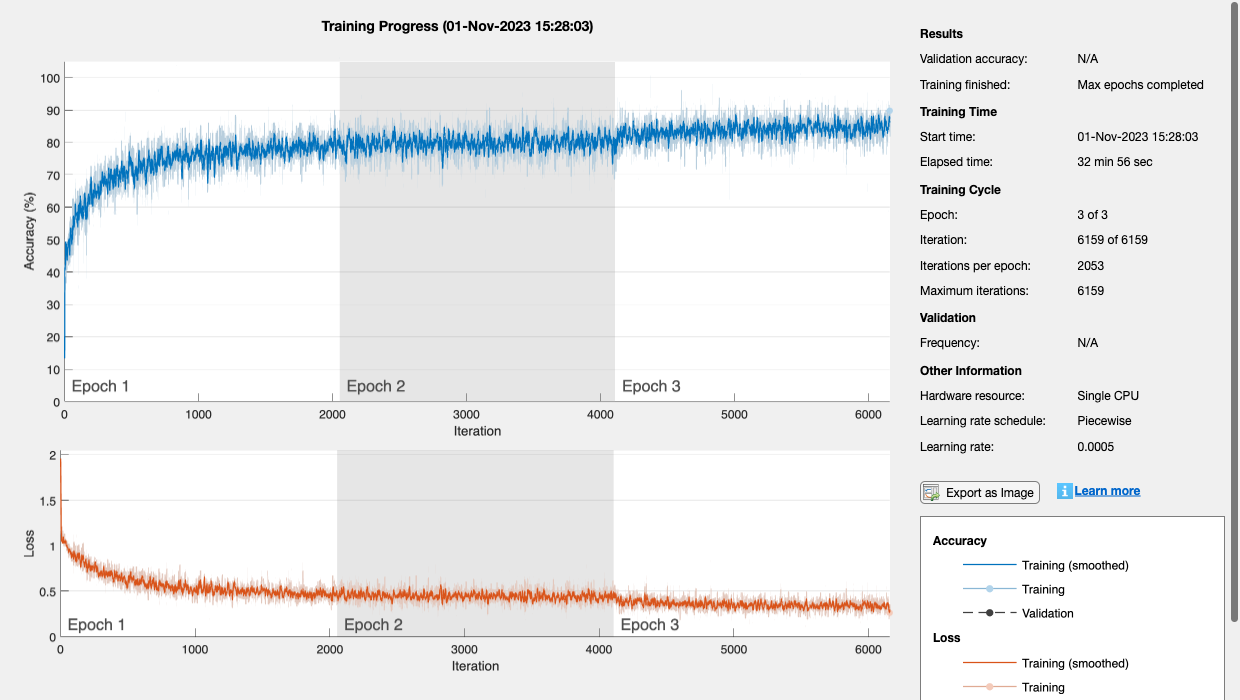

% Train the network using the specified parameters and training dataset
net = trainNetwork(sequencesTrain,labelsTrain,layers,options);

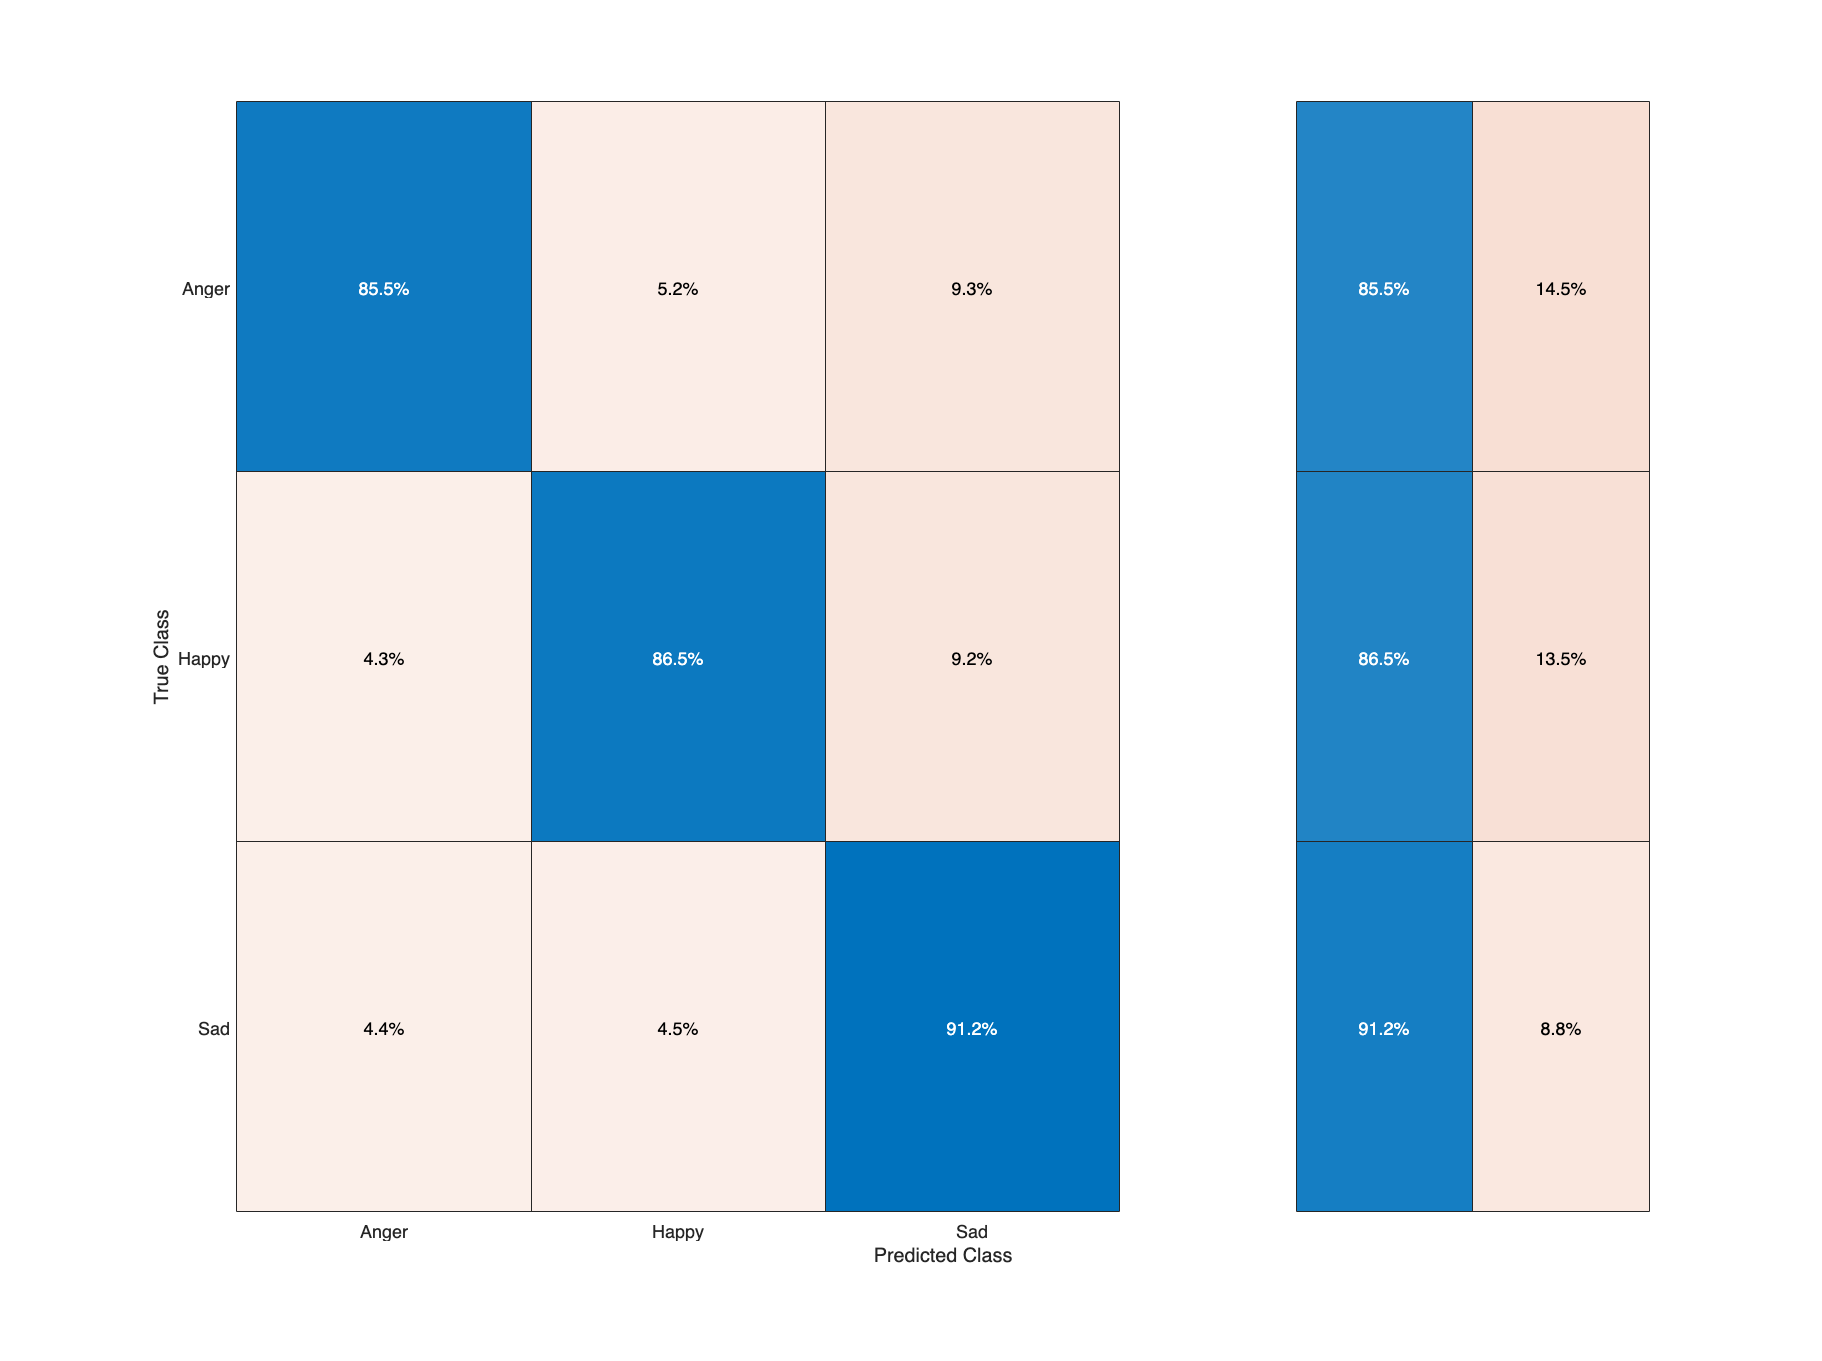

% Predict labels for the training set using the trained network
predictionsTrain = classify(net, sequencesTrain);
labelsTrain = removecats(labelsTrain);
predictionsTrain = removecats(predictionsTrain);
figure; confusionchart(labelsTrain, predictionsTrain,'Normalization','row-normalized','RowSummary','row-normalized');

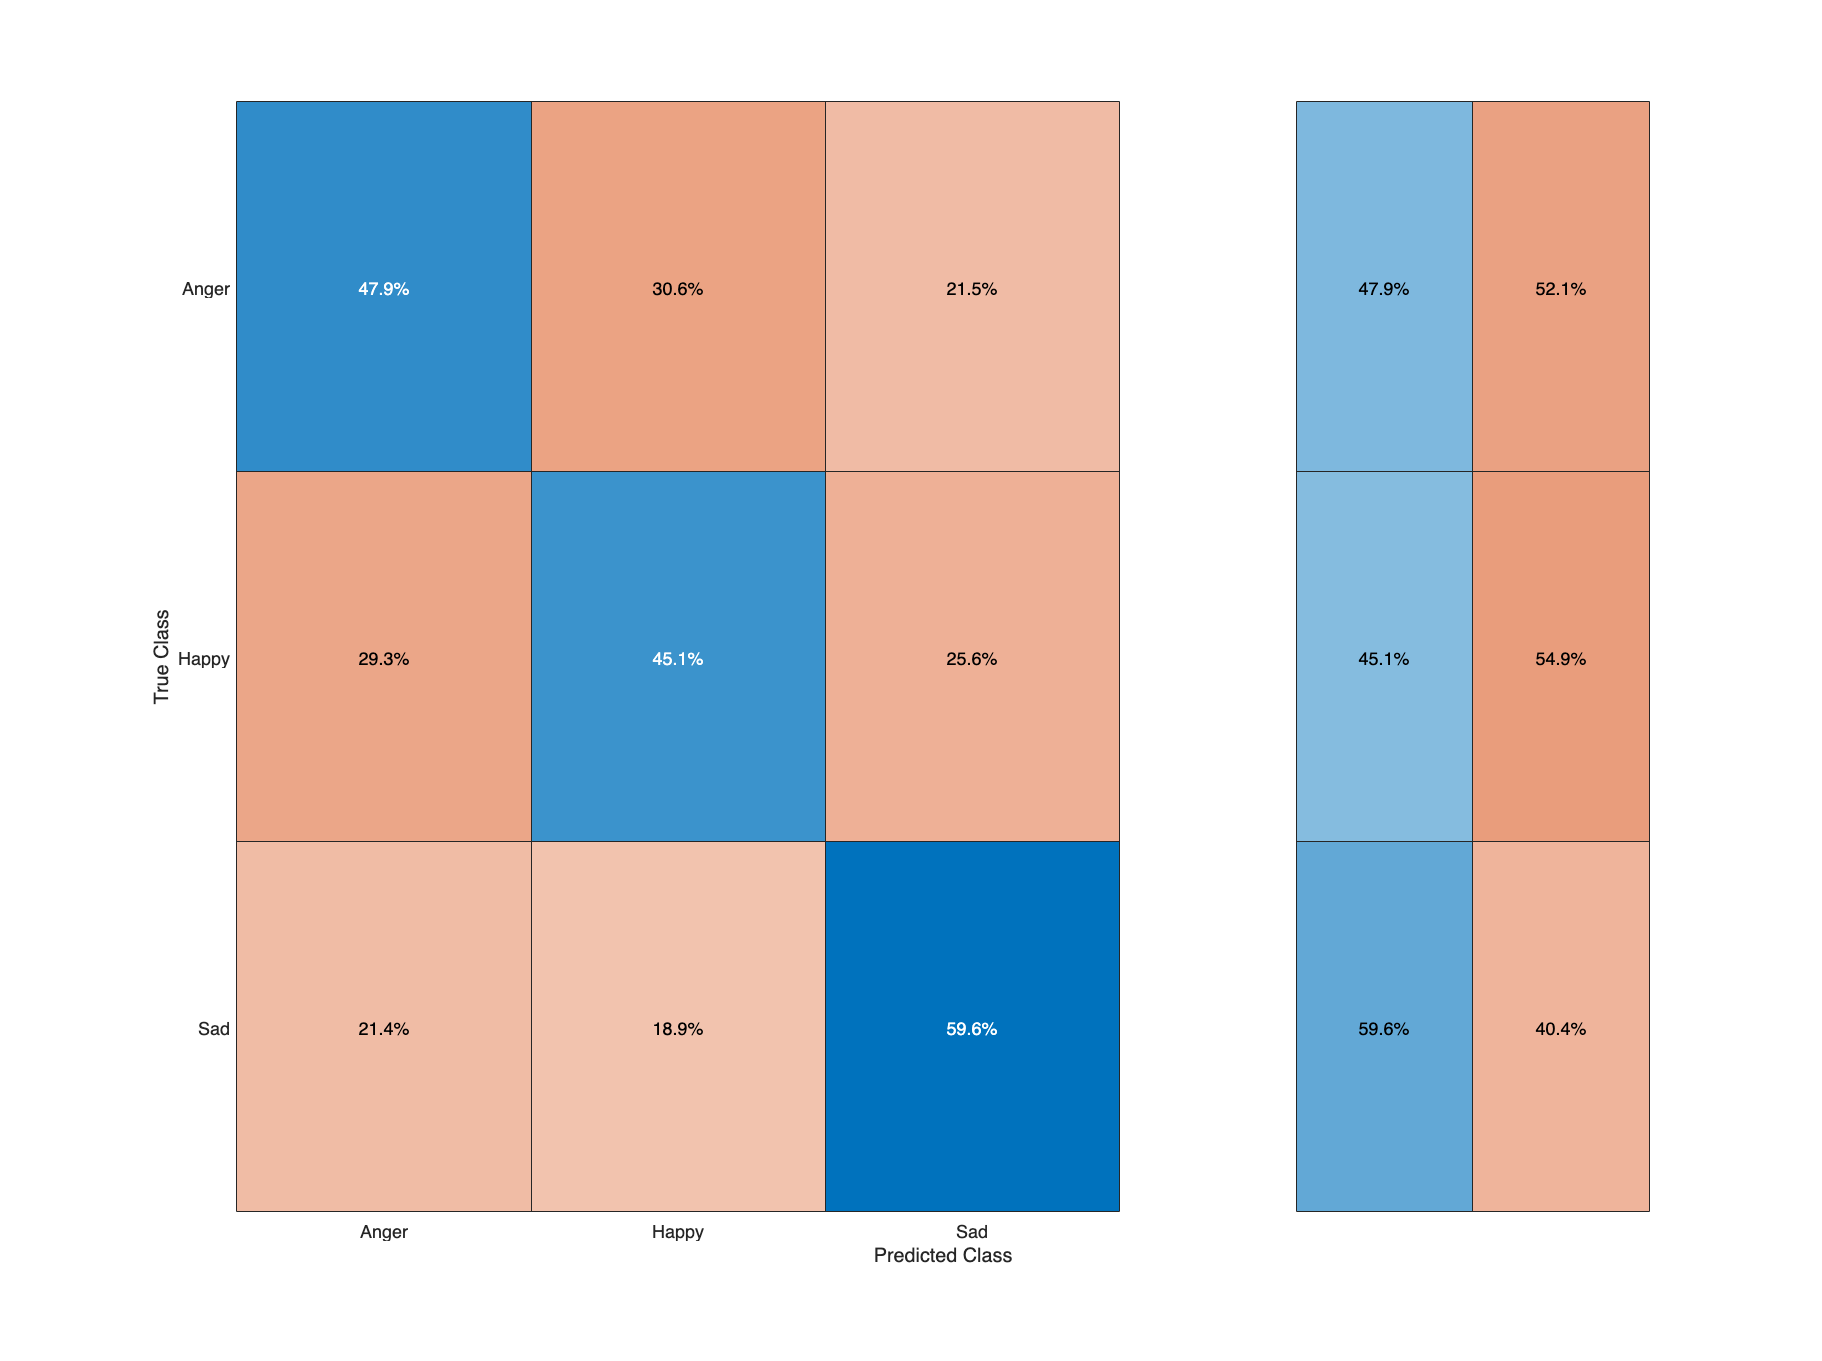

% Predict labels for the test set using the trained network
predictionsTest = classify(net, sequencesTest);
labelsTest = removecats(labelsTest);
predictionsTest = removecats(predictionsTest);
figure; confusionchart(labelsTest, predictionsTest,'Normalization','row-normalized','RowSummary','row-normalized');

% Save all the data to use in LSTM_Cross_Predict.mlx
save("Workspace_EmoDB.mat", "-v7.3");